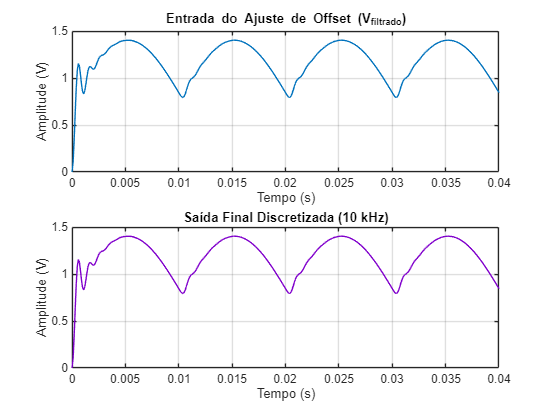

%% Analise_Ajuste_Offset.m
clear; clc; close all;

% Carregar saída do filtro
load('V_filtrado.mat', 'V_filtrado', 't', 'Fs');

% Parâmetros
V_offset = 0;          % Offset desejado
Fs_novo = 10000;       % Nova frequência de amostragem (10 kHz)

% Aplicar offset
V_final = V_offset + V_filtrado;

% Reamostrar usando 'resample'
[V_final_discreto, t_discreto] = resample(V_final, t, Fs_novo);

% Salvar resultado discretizado
save('V_final_discreto.mat', 'V_final_discreto', 't_discreto', 'Fs_novo');

% Plotagem
figure;
subplot(2,1,1);
plot(t, V_filtrado);
title('Entrada do Ajuste de Offset (V_{filtrado})');
xlabel('Tempo (s)'); ylabel('Amplitude (V)'); grid on;

subplot(2,1,2);
plot(t_discreto, V_final_discreto, 'Color', [0.5 0 0.8]);
title('Saída Final Discretizada (10 kHz)');
xlabel('Tempo (s)'); ylabel('Amplitude (V)'); grid on;